%% Parameters (common)
f1 = 3;                 % First frequency (Hz)
t = 0:0.001:1;          % Fine time vector
N_fixed = 15;            % Fixed truncation half-width when not studying N
f2_fixed = 7;           % Fixed second frequency (bandwidth) when not studying f2
fs_fixed = 14;          % Fixed sampling rate when not studying fs


%% 1. Effect of Sampling Rate
disp('Studying effect of sampling rate...');

Studying effect of sampling rate...


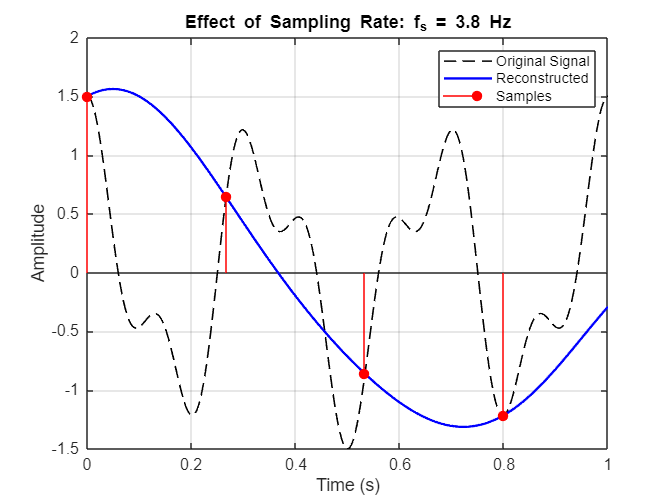

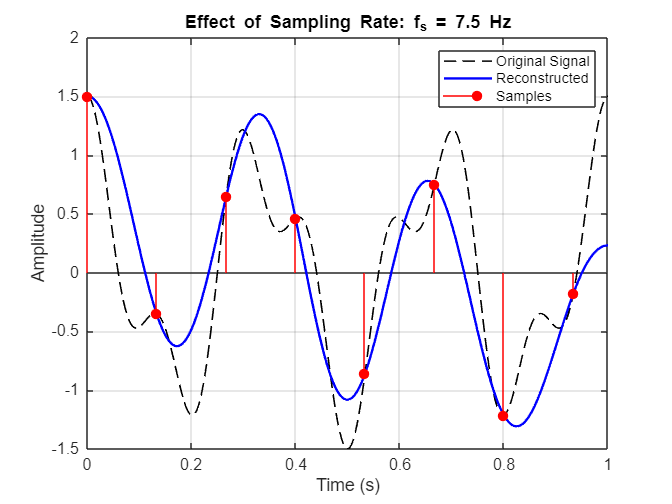

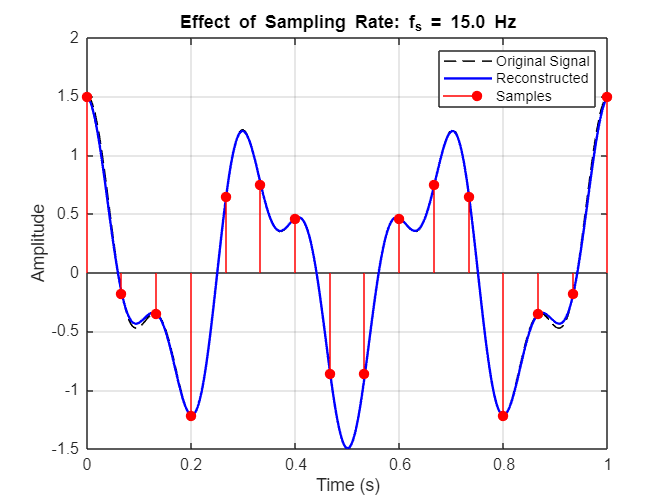

f2 = f2_fixed;          % Keep f2 constant
x_t = cos(2*pi*f1*t) + 0.5*cos(2*pi*f2*t);

fs_list = [3.75, 7.5, 15]; % Different sampling rates

for fs = fs_list
    [t_s, x_s] = sample_signal(t, x_t, fs);
    x_r = reconstruct(t, x_s, fs, N_fixed);

    figure;
    plot(t, x_t, 'k--', 'LineWidth', 1); hold on;
    plot(t, x_r, 'b', 'LineWidth', 1.5);
    stem(t_s, x_s, 'r', 'filled'); hold off;
    legend('Original Signal', 'Reconstructed', 'Samples');
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(sprintf('Effect of Sampling Rate: f_s = %.1f Hz', fs));
    xlim([0, 1]); % Limit x-axis from 0 to 1
    grid on;
end

%% 2. Effect of Truncation Width (Kernel Size)
disp('Studying effect of truncation width...');

Studying effect of truncation width...


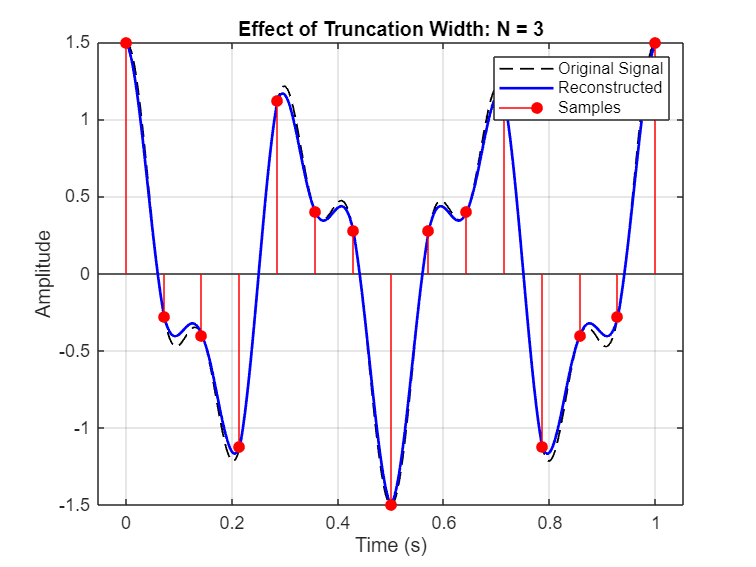

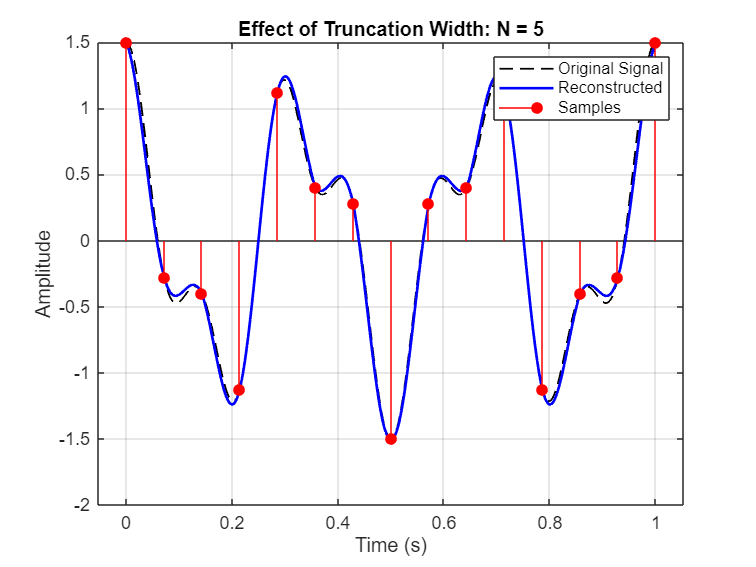

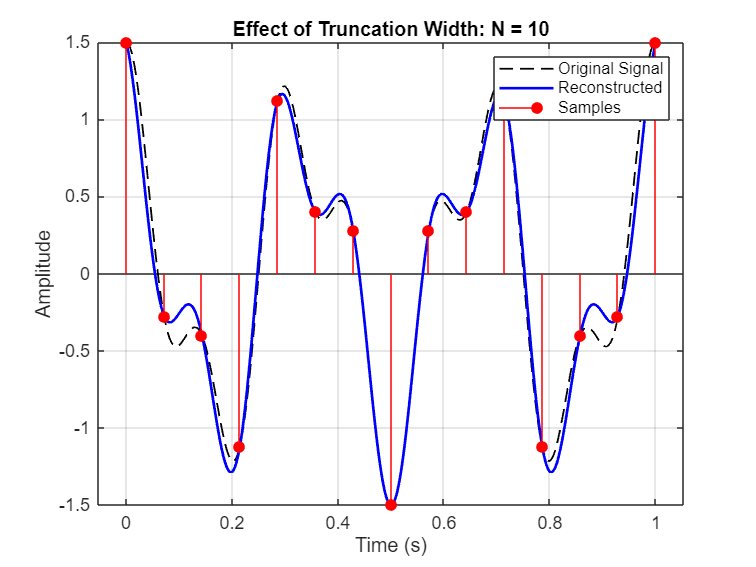

fs = fs_fixed;          % Keep sampling rate constant
f2 = f2_fixed;          % Keep bandwidth constant
x_t = cos(2*pi*f1*t) + 0.5*cos(2*pi*f2*t);
[t_s, x_s] = sample_signal(t, x_t, fs);

N_list = [3, 5, 10];    % Different truncation widths

for N = N_list
    x_r = reconstruct(t, x_s, fs, N);

    figure;
    plot(t, x_t, 'k--', 'LineWidth', 1); hold on;
    plot(t, x_r, 'b', 'LineWidth', 1.5);
    stem(t_s, x_s, 'r', 'filled'); hold off;
    legend('Original Signal', 'Reconstructed', 'Samples');
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(sprintf('Effect of Truncation Width: N = %d', N));
    grid on;
end

%% 3. Effect of Original Signal Bandwidth
disp('Studying effect of signal bandwidth...');

Studying effect of signal bandwidth...


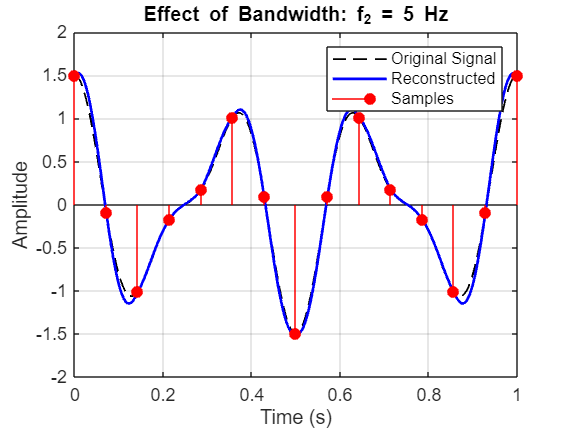

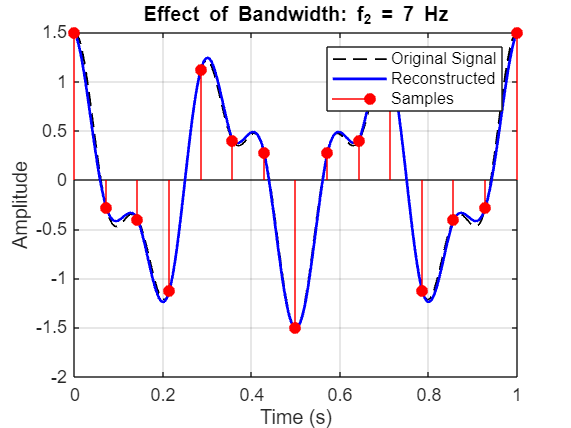

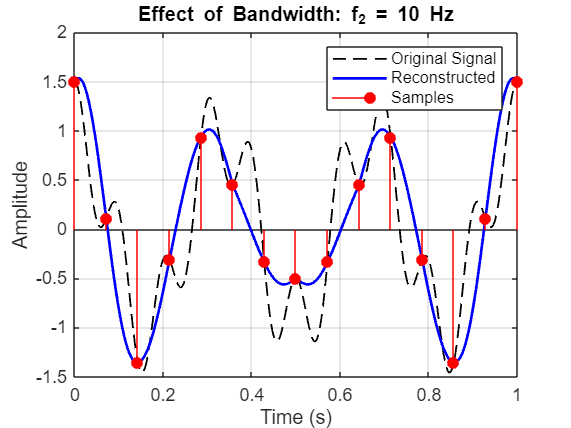

fs = fs_fixed;          % Keep sampling rate constant
N = N_fixed;            % Keep truncation window constant

f2_list = [5, 7, 10];   % Different bandwidths

for f2 = f2_list
    x_t = cos(2*pi*f1*t) + 0.5*cos(2*pi*f2*t);
    [t_s, x_s] = sample_signal(t, x_t, fs);
    x_r = reconstruct(t, x_s, fs, N);

    figure;
    plot(t, x_t, 'k--', 'LineWidth', 1); hold on;
    plot(t, x_r, 'b', 'LineWidth', 1.5);
    stem(t_s, x_s, 'r', 'filled'); hold off;
    legend('Original Signal', 'Reconstructed', 'Samples');
    xlabel('Time (s)');
    ylabel('Amplitude');
    title(sprintf('Effect of Bandwidth: f_2 = %d Hz', f2));
    grid on;
end